# Statistical Analysis 

This lecture will cover several of the statistical analysis tools in MATLAB. 

## Correlation - two variables

Helps identify if a linear relationship exists between two variables

Different types of correlation - Pearson's and Spearman (rank)

- **Pearson's** - measures the strength and direction of a linear relationship between two variables

- **Spearman** - measures the strength and direction of a monotonic relationship between two variables

Both of these measures of correlation are on a scale of -1 to 1.

Consider the two arrays, *A* and *B*: 

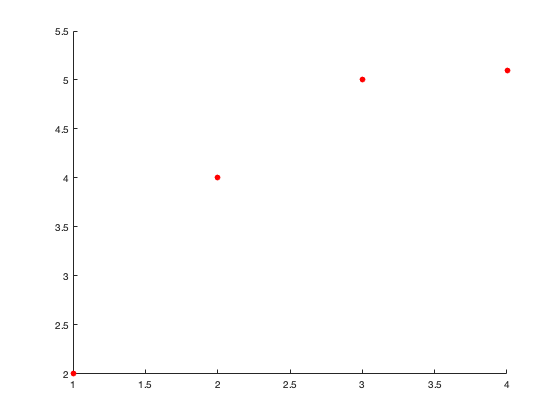

A = [1, 2, 3, 4];
B = [2, 4, 5, 5.1];
scatter(A,B,'red','filled')

Based on the above plot, what values would you guess for the Pearson's and Spearman correlation estimates?

We can use the `corr `function, which outputs the pairwise correlation between the columns of the two matrices. With the `corr` function, we have the option to specify Pearson or Spearman correlation by using the `'type' `option. Note that we have to transpose the arrays in order to arrange the data into columns.

r = corr(A',B',"type","Pearson")

r = 0.9244


r_spear = corr(A',B',"type","Spearman")

r_spear = 1

As expected, the Pearson correlation value is fairly high as the two variables appear to have a strong linear relationship.

The output of 1 for the Spearman correlation also makes sense because the two arrays are completely monotonic, meaning that as one variable increases, so does the other. 

Once we have *r, *we can easily calculate the coefficient of determination, $r^2 

$. The coefficient of determination measures the proportion of variance in the dependent variable that can be explained by the independent variable. 

r_squared = r^2

r_squared = 0.8545

## Correlation - Multiple Variables

We can also examine the correlation between more than two variables. Load the Framingham data set for use in the following examples.

fram = readtable("../frmgham.xls");

Use the `corr` function to find the correlation between systolic and diastolic blood pressure. Note that the default correlation type for `corr` is `"Pearson"`.

corr(fram.SYSBP, fram.DIABP)

ans = 0.7116

When the `corr` function is used on more than two variables, the output is a matrix of the correlation coefficients. Find the correlation between systolic blood pressure, diastolic blood pressure, and age.

corr([fram.SYSBP, fram.DIABP, fram.AGE])

ans =     1.0000    0.7116    0.3890
    0.7116    1.0000    0.0693
    0.3890    0.0693    1.0000


Each value in the matrix corresponds to the correlation between the variables in that particular row and column. For example, the correlation between diastolic blood pressure and age is 0.0693.

This same process can be used for any number of variables. We will now analyze the variables in columns 2 thru 11 of the Framingham data set. First, extract these columns from the full data set.

fram_2_11 = fram(:,2:11);

What variables are included in these ten columns?

var_names = fram_2_11.Properties.VariableNames;
var_names' 

ans = 10×1 cell array
    {'SEX'     }
    {'TOTCHOL' }
    {'AGE'     }
    {'SYSBP'   }
    {'DIABP'   }
    {'CURSMOKE'}
    {'CIGPDAY' }
    {'BMI'     }
    {'DIABETES'}
    {'BPMEDS'  }


In order for the `corr `function to work correctly, we need to remove the observations containing NaN. For this process, you can use the `rmmissing` command, which removes any rows with missing data.

fram_noNaN = rmmissing(fram_2_11);

Now that the NaN values have been removed from the matrix, we can find the correlation coefficients.

r = corr(fram_noNaN.Variables)

r =     1.0000    0.1309    0.0267    0.0438   -0.0526   -0.1562   -0.2514   -0.0740   -0.0232    0.0838
    0.1309    1.0000    0.1655    0.1580    0.1360   -0.0483   -0.0372    0.0843    0.0060    0.0612
    0.0267    0.1655    1.0000    0.3832    0.0576   -0.2522   -0.2253    0.0612    0.1323    0.2002
    0.0438    0.1580    0.3832    1.0000    0.7108   -0.1438   -0.1011    0.2707    0.1362    0.3287
   -0.0526    0.1360    0.0576    0.7108    1.0000   -0.0750   -0.0298    0.3340    0.0229    0.2267
   -0.1562   -0.0483   -0.2522   -0.1438   -0.0750    1.0000    0.7806   -0.1648   -0.0429   -0.0896
   -0.2514   -0.0372   -0.2253   -0.1011   -0.0298    0.7806    1.0000   -0.0996   -0.0451   -0.0845
   -0.0740    0.0843    0.0612    0.2707    0.3340   -0.1648   -0.0996    1.0000    0.0889    0.0984
   -0.0232    0.0060    0.1323    0.1362    0.0229   -0.0429   -0.0451    0.0889    1.0000    0.0770
    0.0838    0.0612    0.2002    0.3287    0.2267   -0.0896   -0.0845    0.0984    0.0

Use the `maxk` function to find five highest correlation features (positive or negative) for each variable as well as the index. We will specify for the function to return the five largest values for each column, the indices of these vaues, and to use absolute values to find the maximums.  

[max_corr, I] = maxk(r,5,"ComparisonMethod","abs")

max_corr =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.2514    0.1655    0.3832    0.7108    0.7108    0.7806    0.7806    0.3340    0.1362    0.3287
   -0.1562    0.1580   -0.2522    0.3832    0.3340   -0.2522   -0.2514    0.2707    0.1323    0.2267
    0.1309    0.1360   -0.2253    0.3287    0.2267   -0.1648   -0.2253   -0.1648    0.0889    0.2002
    0.0838    0.1309    0.2002    0.2707    0.1360   -0.1562   -0.1011   -0.0996    0.0770    0.0984


I =      1     2     3     4     5     6     7     8     9    10
     7     3     4     5     4     7     6     5     4     4
     6     4     6     3     8     3     1     4     3     5
     2     5     7    10    10     8     3     6     8     3
    10     1    10     8     2     1     4     7    10     8


We can make the top ranking features much easier to interpret by creating tables with the variable names as opposed to the indices.

corr_table = array2table(max_corr, "VariableNames",var_names);
I_table = array2table(var_names(I),"VariableNames",var_names)

I_table = 5×10 table
       SEX         TOTCHOL        AGE         SYSBP        DIABP       CURSMOKE      CIGPDAY         BMI         DIABETES      BPMEDS 
    __________    _________    __________    ________    _________    __________    __________    __________    __________    ________

    'SEX'         'TOTCHOL'    'AGE'         'SYSBP'     'DIABP'      'CURSMOKE'    'CIGPDAY'     'BMI'         'DIABETES'    'BPMEDS'
    'CIGPDAY'     'AGE'        'SYSBP'       'DIABP'     'SYSBP'      'CIGPDAY'     'CURSMOKE'    'DIABP'       'SYSBP'       'SYSBP' 
    'CURSMOKE'    'SYSBP'      'CURSMOKE'    'AGE'       'BMI'        'AGE'         'SEX'         

Looking at these two tables, what are some of the variables with the highest correlation? We have to ignore the 1's because those values correspond to the variable's correlation with itself. Aside from the 1's in the correlation coefficient matrix, what are the three highest values and what features do they correspond to?

- Correlation = 0.7806 - CIGPDAY, CURSMOKE

- Correlation = 0.7108 - SYSBP, DIABP

- Correlation = 0.3832 - SYSBP, AGE

Does it makes sense that these variables have strong linear relationships? Are there any other variables that you would expect to have high correlation coefficients?

Repeat the same process on columns 2-11 of the Framingham data set, but this time using rank correlation. 

r_rank = corr(fram_noNaN.Variables,'type','Spearman');
[max_corr_rank, I_rank] = maxk(r_rank,5,"ComparisonMethod","abs");
max_corr_rank = array2table(max_corr_rank,"VariableNames",var_names)

max_corr_rank = 5×10 table
      SEX       TOTCHOL      AGE        SYSBP      DIABP     CURSMOKE    CIGPDAY       BMI       DIABETES     BPMEDS  
    ________    _______    ________    _______    _______    ________    ________    ________    ________    _________

           1          1           1          1          1           1           1           1           1            1
    -0.21494    0.18332     0.39141    0.70835    0.70835     0.95091     0.95091      0.3235     0.13091      0.29577
    -0.15617    0.17211    -0.25512    0.39141     0.3235    -0.25205    -0.25512     0.26655      0.1207      0.21263
      -0.135    0.14708    -0.25205  

I_rank = array2table(var_names(I_rank),"VariableNames",var_names)

I_rank = 5×10 table
       SEX         TOTCHOL        AGE         SYSBP        DIABP       CURSMOKE      CIGPDAY         BMI         DIABETES      BPMEDS  
    __________    _________    __________    ________    _________    __________    __________    __________    __________    _________

    'SEX'         'TOTCHOL'    'AGE'         'SYSBP'     'DIABP'      'CURSMOKE'    'CIGPDAY'     'BMI'         'DIABETES'    'BPMEDS' 
    'CIGPDAY'     'AGE'        'SYSBP'       'DIABP'     'SYSBP'      'CIGPDAY'     'CURSMOKE'    'DIABP'       'AGE'         'SYSBP'  
    'CURSMOKE'    'SYSBP'      'CIGPDAY'     'AGE'       'BMI'        'AGE'         'AGE'      

Do the same features have the strongest correlation coefficients?

- Correlation = 0.9509 - CIGPDAY, CURSMOKE

- Correlation = 0.7084 - SYSBP, DIABP

- Correlation = 0.3914 - SYSBP, AGE

While the correlation coefficients are different from the Spearman's rank test, the variables with the strongest linear relationships are the same. 

## Visualizing Correlations

Heatmaps use color-coding to compare data, making it easy to observe variable relationships and patterns. Heatmaps are a useful tool for visualizing pairwise correlations. The `heatmap` command in MATLAB accepts both tables and matrices as inputs. 

Create a heatmap for the pairwise correllations of our ten variables.

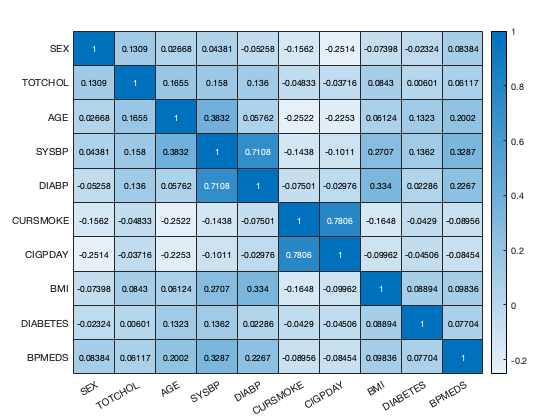

h = heatmap(r);
h.XDisplayLabels = var_names;
h.YDisplayLabels = var_names;

The heatmap makes it very easy to pick out the highest and lowest correlated features.  

Another tool in MATLAB for visualizing raw data correlations is `gplotmatrix`. This command creates a matrix of scatter plots for each variable in the data set against every other variable. 

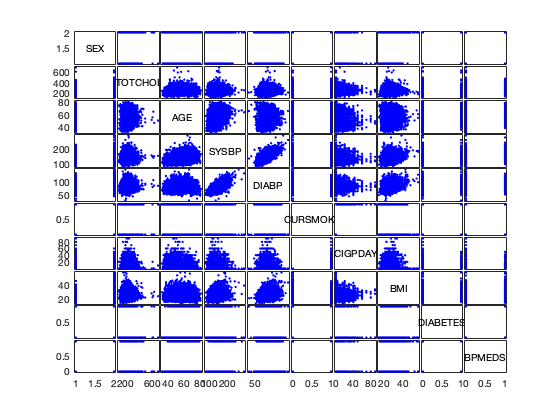

gplotmatrix(fram_noNaN.Variables,[],[],[],[],[],[],'variable',var_names);

## Regression

General steps for building a regression model:

- Start with a hypothesis or specific goal (e.g. predicting BMI from age)

- Identify the feature you want to predict, the response variable (e.g. BMI)

- Identify the predictors - age, sex, heart rate (the input data)

- Do you expect a linear relationship?

- Visualize variables using plot functions

### Regression - Creating a Model

When creating a regression model, it is helpful to start with the simplest model (single variable) and then gradually increase the complexity. 

Simple linear regression is used for the two-variable models. With linear regression, we examine the explanatory variable and the response variable, and try to fit a linear equation to the data: $Y_1 =b*X$, where $Y_1$ is the predicited value and *b *is the regression coefficient.

Can we predict BMI from total cholesterol? There are two ways to find the slope (regression coefficient) of single-variable linear regression models*.*

1.) Use the `\` operator.

fram_noNaN.TOTCHOL \ fram_noNaN.BMI

ans = 0.1037

2.) Use the `regress` function. The `regress` function removes NaN values, so we can use the original data. Before carrying out the command, assign the total cholesterol and BMI arrays to variables X and Y, respectively.

X = fram.TOTCHOL;
Y = fram.BMI;
b = regress(Y,X)

b = 0.1038

These two methods produce the same results for *b*. In terms of predicting BMI from total cholesterol, we now have the equation $Y_1 =b*X$, where $Y_1$ is estimated BMI, *b *is the regression coefficient, and *X *is total cholesterol. Create an array containing the predicted BMI values using this equation.

Y1 = b*X;

To improve the regression model, we want to include an intercept term. In order to do this, a column of ones must be added to independent variable matrix.

X_ones = [ones(size(X)) X];

Now repeat the `regress` command with the new X variable*.*

b2 = regress(Y,X_ones)

b2 =    24.1091
    0.0072


The first term in the *b *array is the y-intercept for the linear regression line, and the second term is the slope. We now have the equation $Y_1 =b_0 *X+b_1$. Use these values to create an array which contains the new values for $Y_1$. 

Y2 = b2(2)*X_ones(:,2)+b2(1);

How do the two estimates for $Y_1$ compare? And how do these compare to that actual BMI data? Use the `scatter` function to compare.

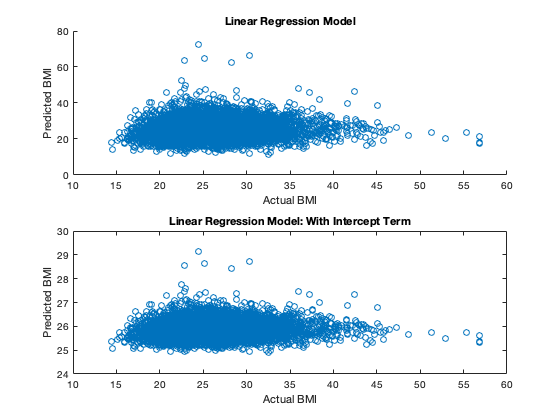

subplot(2,1,1)
scatter(Y,Y1)
xlabel('Actual BMI')
ylabel('Predicted BMI')
title('Linear Regression Model')

subplot(2,1,2)
plot(Y,Y2,'o')
xlabel('Actual BMI')
ylabel('Predicted BMI')
title('Linear Regression Model: With Intercept Term')

### Regression Model - Forecasting

We can use the regression model to predict impact in new conditions. 

Predict the BMI for a hypothetical person with a total cholesterol value of 200.

BMI_200 = b2(2)*200 + b2(1)

BMI_200 = 25.5538

### Regression - Predicting New Values

Using the regression coefficient, we can examine how the predicted BMI changes with total cholesterol. For example, make an array of values from the minimum to maximum cholesterol values in increments of 10.

chol_range = min(X):10:max(X);

Create an array which contains the corresponding predicted BMI values.

Y1_predict = b2(2)*chol_range+b2(1);

Create a scatter plot with the new$\;Y_1$.

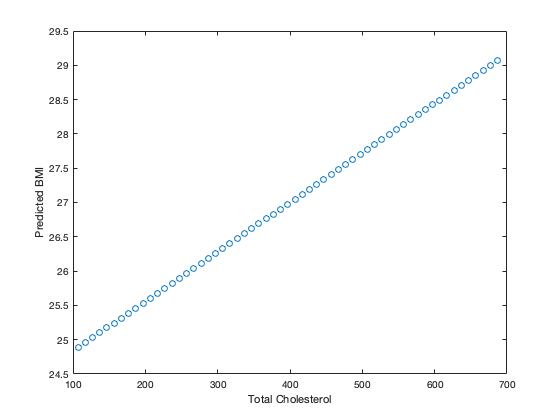

figure
scatter(chol_range,Y1_predict)
xlabel('Total Cholesterol')
ylabel('Predicted BMI')

We can also insert a best fit line on the original data set using the `lsline` function.

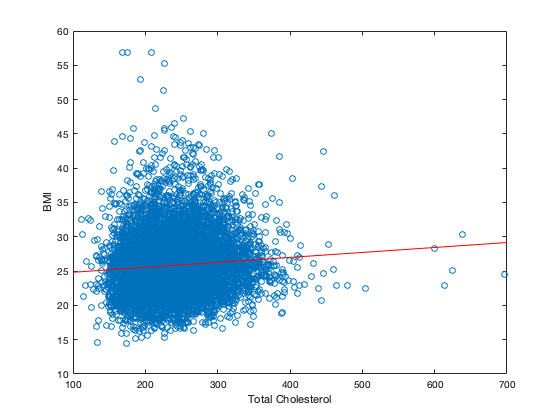

plot(X,Y,'o')
xlabel('Total Cholesterol')
ylabel('BMI')
h = lsline;
h.Color = 'r';

Another method for performing linear regression uses the `fitlm `command. The `fitlm` command outputs a linear regression model when given the predicting variable and the response variable.

fitlm(X,Y)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)       24.109       0.20852    115.62             0
    x1             0.0072236    0.00084972    8.5012    2.1157e-17


Number of observations: 11173, Error degrees of freedom: 11171
Root Mean Squared Error: 4.07
R-squared: 0.00643,  Adjusted R-Squared: 0.00634
F-statistic vs. constant model: 72.3, p-value = 2.12e-17

The intercept and regression coefficient terms from the `fitlm `function give us the same equation for the best fit line as when we used the `regress` function: $Y_{1\;} =0\ldotp 0072X+24\ldotp 1\ldotp$

### Regression - Systolic and Diastolic BP

Create a linear model which uses systolic blood pressure to predict diastolic blood pressure. Plot the data points, the best fit line and find the linear regression equation.

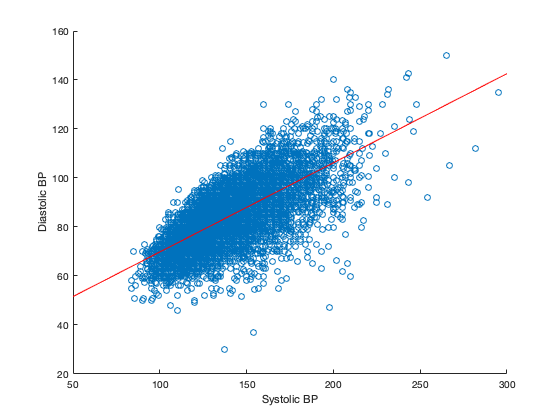

scatter(fram.SYSBP,fram.DIABP)
xlabel('Systolic BP')
ylabel('Diastolic BP')
h = lsline;
h.Color = 'r';

fitlm(fram.SYSBP,fram.DIABP)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue
                   ________    _________    ______    ______

    (Intercept)     33.421       0.46061    72.558      0   
    x1             0.36396     0.0033325    109.22      0   


Number of observations: 11627, Error degrees of freedom: 11625
Root Mean Squared Error: 8.19
R-squared: 0.506,  Adjusted R-Squared: 0.506
F-statistic vs. constant model: 1.19e+04, p-value = 0

The equation for the best fit line is $\mathrm{DIABP}=0\ldotp 364*\mathrm{SYSBP}+33\ldotp 421\ldotp \;$The positive slope indicates that diastolic blood pressure increases with systolic blood pressure. The $r^2$ value of 0.506 indicates that there is a fairly strong linear relationship between the two variables.

## Multi-linear Regression

Most diseases and biomedical processes involve multiple parameters. In these instances, several variables may be needed to accurately predict the response variable. 

For example, BMI may be a function of age, sex, glucose, cholesterol and heart rate. The `regress `function can still be used for multi-linear regression models. To create a linear regression model with these variables, we will make a matrix containing all of the predictors plus the column of ones.

X_multi = [ones(size(fram.AGE)), fram.AGE, fram.SEX, fram.TOTCHOL, fram.GLUCOSE,...
fram.HEARTRTE];
Y_multi = fram.BMI;
b_multi = regress(Y_multi,X_multi)

b_multi =    22.3565
    0.0148
   -0.7409
    0.0074
    0.0113
    0.0141


What do the outputs of the `regress` function tell us about our model? These values are the regression weights and correspond to the effect of each independent variable on the dependent variable. 

Most of the features have positive correlations with BMI. We expect for BMI to increase with age, total cholesterol, glucose levels and heart rate. However, our model indicates that BMI decreases with the value for sex (1 for males, 2 for females). This suggests that on average, males have higher BMI than females.

### Multi-linear Regression - Assess Accuracy

To obtain more information about the linear regression model when using the `regress` command, use the *stats* option. This option provides the $r^2$ statistic, *F*-statistic, *p*-value, and estimated error variance.

Find the $r^2$ value for the single-variable and multi-variable regression models that we made for predicting BMI from total cholesterol.

[b,~,~,~,stats] = regress(Y,X_ones);
b
stats(1)
[b_multi,~,~,~,stats_multi] = regress(Y_multi,X_multi);
b_multi
stats_multi(1)

The $r^2$ value increased from 0.0064 to 0.0235 from the single-variable model to the multi-variable model. 

While both values are very low, it makes sense that the $r^2$ value for the multi-variable linear regression is higher as we have more predicting factors for the BMI.

## Logistic Regression 

Logistic regression is used for discrete categorical data (in contrast to continuous data for linear regression).

Example – Classifying patients with diabetes versus those without diabetics.

Similar to the `regress` and `fitlm `functions, we can use the `mnrfit` function to predict diabetes from multiple variables. The `mnrfit` command returns a matrix of coefficient estimates for a multinomial logistic regression of the response variable based on the predictor variables.

Note that the response variable must be discrete, but the predictors can be continuous. We will start with just one predictor, blood glucose levels.

First, the diabetes data set must be converted to a categorical array.

diabetes = categorical(fram.DIABETES);

The first category is *non-diabetic*, represented by 0's. The second and last category is *diabetic*, represented by 1's. The `mnrfit` function will always use the last category as the "reference" category. The model that is returned by the function indicates the risk of being non-diabetic versus diabetic. This is especially important to remember when there are more than two categories in the response variable. 

Now that we have the categorical response variable, we can use `mnrfit` to create the model.

[B1,~,stats] = mnrfit(fram.GLUCOSE, diabetes);

b =    24.1091
    0.0072


B1

ans = 0.0064

The first value in B1 contains the intercept term for the relative risk model. The second row contains the slope corresponding to glucose levels. This model for relative risk can be represented by the following equation:


$$\mathrm{ln}\left(\frac{\pi_{\mathrm{non}-\mathrm{diabetic}} }{\pi_{\mathrm{diabetic}} }\right)=8\ldotp 5446-0\ldotp 0565X_1$$


The model coefficients provide information about the relative risk of being in one category versus another. In this example, the coefficient -0.0565 indicates that the relative risk of being non-diabetic versus diabetic decreases exp(0.0565) for every each unit increase in glucose, if all else is equal.

Now include glucose, BMI and total cholesterol in the predictor data set.

predictors = [fram.GLUCOSE, fram.BMI, fram.TOTCHOL];
[B1,~,stats] = mnrfit(predictors,diabetes);

b_multi =    22.3565
    0.0148
   -0.7409
    0.0074
    0.0113
    0.0141


B1

ans = 0.0235

This model for relative risk can be represented by the following equation:


$$\mathrm{ln}\left(\frac{\pi_{\mathrm{non}-\mathrm{diabetic}} }{\pi_{\mathrm{diabetic}} }\right)=10\ldotp 6017-0\ldotp 0567X_1 -0\ldotp 067X_2 -0\ldotp 009X_3$$


where $X_1$is glucose, $X_2$ is BMI, and $X_3$ is total cholesterol.

We can also check if each model coefficient is statistically significant.

stats.p

We typically look for a p-value below 0.05 for determining whether the hypothesis is significant or not. The last p-value, which corresponds to total cholesterol, is much greater than 0.05, indicating that this coefficient is not significant to the model. 

### Logistic Regression - Forecasting for New data sets

We can use the `mnrval` function to evaluate the response variable (i.e. Diabetes) for new values of the predictor variables. The inputs for `mnrval` include the coefficient estimates we created with the `mnrfit `function and the values for the predictor variables that we want to analyze. The output of the function indicates the probability of belonging to each response category (Diabetic vs Non-Diabetic). 

Example: Predict if a person with Glucose =90, BMI = 24, and Cholesterol = 200 has diabetes.

x = [90 24 200];
mnrval(B1,x)

B1 =     8.5446
   -0.0565


Based on these results, a person with these BMI, cholesterol and glucose levels has a 2.4% chance of having diabetes. Keep in mind that only 530 of the 11627 patients in the data set (4.56%) are diabetic. 

Repeat the prediction for a person with the following characteristics: Glucose = 160, BMI = 29, Cholesterol = 200.

x = [160 29 200];
mnrval(B1,x)

As expected, this patient has higher BMI and glucose levels and therefore is much more likely (64.5%) to have diabetes.

Use the same method to predict whether a patient suffered a stroke during the study (1) or not (0) based on their age, systolic blood pressure and cigarettes smoked per day. We will look at two different patients with the following characteristics: 

- **Patient 1:** Age = 50, Systolic Blood Pressure = 140, Cigarettes Smoked per Day = 6

- **Patient 2:** Age = 30, Systolic Blood Pressure = 115, Cigarettes Smoked per Day = 0

stroke = categorical(fram.STROKE);

B1 =    10.6017
   -0.0567
   -0.0670
   -0.0009


predictors = [fram.AGE,fram.SYSBP,fram.CIGPDAY];
[B2,~,stats] = mnrfit(predictors,stroke);
B2

x1 = [50,140,6];

ans =     0.0000
    0.0000
    0.0000
    0.4599


prob_stroke_1 = mnrval(B2,x1)
x2 = [30,115,0];
prob_stroke_2 = mnrval(B2,x2)

As we might expect, Patient 2 has a lower probability (1.17%) of having suffered a stroke compared to Patient 1 (5.89%) due to their lower age, blood pressure and cigarette-use.

### Polynomial Regression

The `polyfit `function is similar to `regress`, however it is more general in that `polyfit `can be used for linear, quadratic or polynomial models. The function returns the coefficients in descending powers and their length is *n+1. *

Create a first order model for systolic and diastolic blood pressure.

p = polyfit(fram.SYSBP,fram.DIABP,1)

These coefficients represent the following best fit equation: $p\left(x\right)=0\ldotp 364x+33\ldotp 42$

We can use the `polyval` function to plot the calculate the polynomial's value, *p*, at each point, *x*. Plot the original blood pressure data and the first-order best fit line on the same graph.

x1 = linspace(0,max(fram.SYSBP));

ans =     0.9760    0.0240


y1 = polyval(p,x1);
figure
scatter(fram.SYSBP,fram.DIABP)
xlabel('Systolic BP')
ylabel('Diastolic BP')

ans =     0.3551    0.6449


hold on
plot(x1,y1)
hold on

Use `polyfit` once again, this time to create a quadratic model of the systolic and diastolic blood pressure relationship.

p2 = polyfit(fram.SYSBP,fram.DIABP,2)

These coefficients form the following quadratic equation: $p\left(x\right)=-0\ldotp 0013x^{2\;} +0\ldotp 7439x+6\ldotp 305$

Add this best fit line to the previous plot.

B2 =     8.3484
   -0.0548
   -0.0197
   -0.0125


prob_stroke_1 =     0.9411    0.0589


prob_stroke_2 =     0.9883    0.0117


p =     0.3640   33.4209


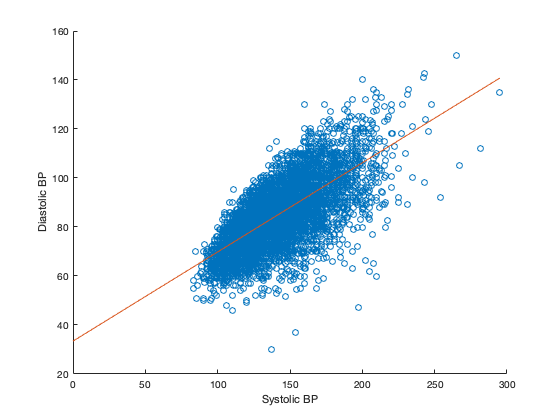

p2 =    -0.0013    0.7439    6.3051


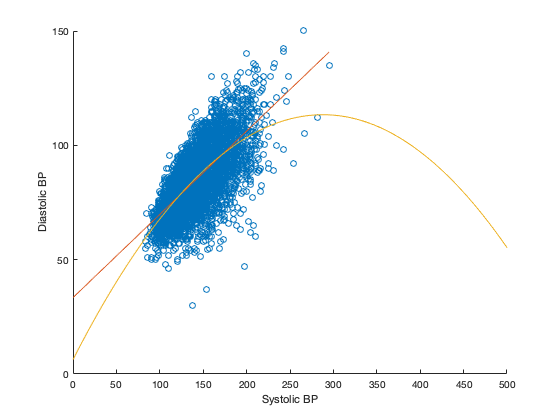

y2 = polyval(p2,0:500);
plot(0:500,y2)
hold off

In regression analysis, it is important to keep the order of the model as low as possible. In this example, it appears that the first-order model actually fits the data better. The use of polynomials of higher orders can lead to incorrect evaluations. 